SNR = -5:5:25;

jmmd.ls = [1.23564 0.78564 0.80065 0.52463 0.74347 0.76276 0.83564] ; 
jmmd.li = [2.30124 2.15643 1.98264 1.97356 2.05701 2.36542 2.48534];
jmmd.prac = [1.94562 1.71516 1.83354 2.19967 2.15652 2.17246 2.40068];

onlySource.ls = [1.54545 0.91204 1.34526 0.87532 1.13121 1.15565 1.22364];
onlySource.li = [3.56456 2.35786 1.90172 2.24354 2.15230 2.06435 2.15623];
onlySource.prac = [     2.0           1.69873 1.85661 2.05321 1.95652 1.88898 2.08576];

myBlue   = [0 0.4470 0.7410];   % MATLAB default blue
myOrange = [0.8500 0.3250 0.0980];
myYellow = [0.9290 0.6940 0.1250];
myPurple = [0.4940 0.1840 0.5560];
myGreen  = [0.4660 0.6740 0.1880];
myCyan   = [0.3010 0.7450 0.9330];
myRed    = [0.6350 0.0780 0.1840];

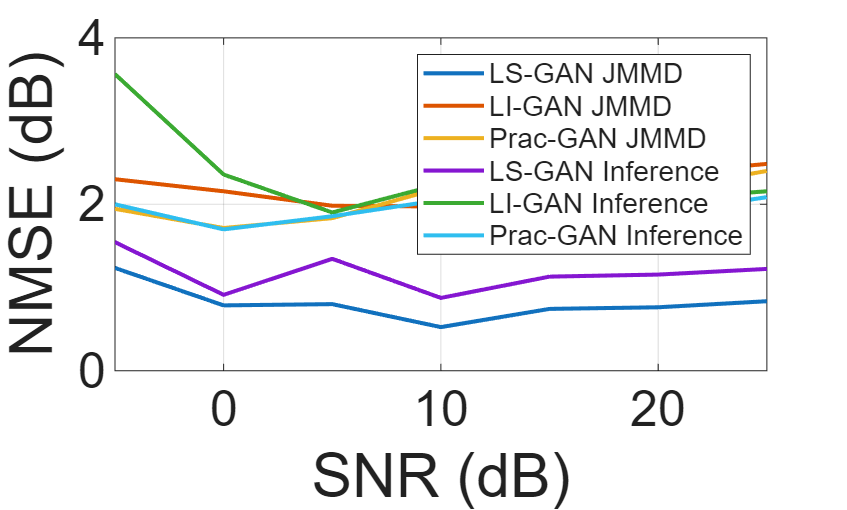

figure;
plot(SNR, jmmd.ls, 'LineWidth', 2.0, 'DisplayName', 'LS-GAN JMMD');
hold on;
plot(SNR, jmmd.li, 'LineWidth', 2.0, 'DisplayName', 'LI-GAN JMMD');
plot(SNR, jmmd.prac, 'LineWidth', 2.0, 'DisplayName', 'Prac-GAN JMMD');

plot(SNR, onlySource.ls, 'LineWidth', 2.0, 'DisplayName', 'LS-GAN Inference');
plot(SNR, onlySource.li, 'LineWidth', 2.0, 'DisplayName', 'LI-GAN Inference');
plot(SNR, onlySource.prac, 'LineWidth', 2.0, 'DisplayName', 'Prac-GAN Inference');
xlim([-5 25]);

set(gca, 'FontSize', 25);
legend('FontSize',14)
grid on
xlabel('SNR (dB)', 'FontSize', 30);
ylabel('NMSE (dB)', 'FontSize', 30);